T = 1:400;
N = 10;
tmin = 25;
t0 = 1;
u = binrand(T, N, tmin, t0, 'normal');

x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


x =     0.0000    0.0001    0.0004    0.0011    0.0025    0.0057    0.0118    0.0231    0.0424    0.0730    0.1180    0.1800    0.2591    0.3531    0.4571    0.5642    0.6667    0.7581    0.8339    0.8923    0.9342    0.9623    0.9797    0.9898    0.9952    0.9979    0.9991    0.9997    0.9999    1.0000


% Define the transfer functions
numerator = [1, 0];
denominator = [10, -10];
ts = 0.01;
C = tf(numerator, denominator, ts);

num = [0.1812];
den = [1, -0.8187];
G = tf(num, den, ts);

variance1 = 0.1; % also for 0.01 and 0.001
variance2 = 0.01;
variance3 = 0.001;
noise1 = sqrt(variance1) * randn(size(u));
noise2 = sqrt(variance2) * randn(size(u));
noise3 = sqrt(variance3) * randn(size(u));

Ts = 0.01;                % Sample time of the models
N = length(u); 
timeVector = 0:Ts:(N-1)*Ts;

output1 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise1.', timeVector.');
output2 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise2.', timeVector.');
output3 = lsim((G*C)/(1+(G*C)), u.', timeVector.') + lsim(1/(1+C*G), noise3.', timeVector.');

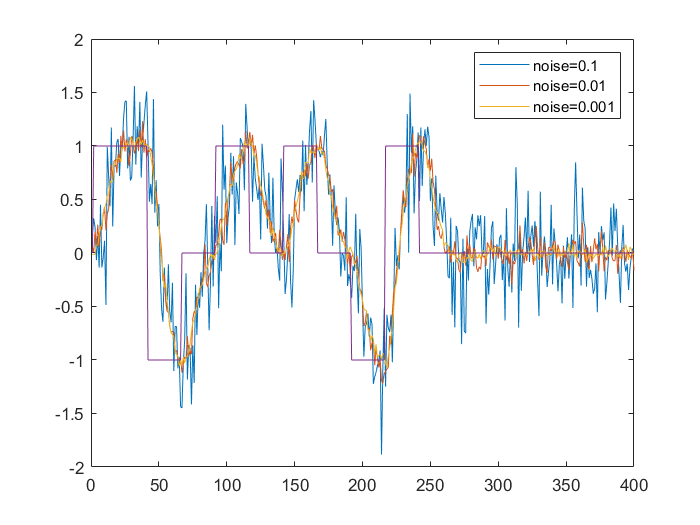

figure;
plot(output1)
hold on
plot(output2)
plot(output3)
plot(u)
legend('noise=0.1','noise=0.01', 'noise=0.001');
hold off

pairs1 = table(u.', output1, 'VariableNames', {'Input', 'Output'});
pairs2 = table(u.', output2, 'VariableNames', {'Input', 'Output'});
pairs3 = table(u.', output3, 'VariableNames', {'Input', 'Output'});

% Define a range of values for na, nb, and nk
% Parameters
na_values = [1, 2, 3 ,4 ];  % List of 'na' values to test
nc_values = [1, 2, 3 ,4];  % List of 'na' values to test
nb_values = [1, 2, 3 ,4 ];  % List of 'nb' values to test
nf_values = [1, 2, 3 ,4];  % List of 'na' values to test
nd_values = [1, 2, 3 ,4];  % List of 'na' values to test
nk_values = [0, 1, 2, 3 ,4];  % List of 'nk' values to test
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model

% Armax with 0.1 noise
best_y_pred = [];  

% Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
for na = na_values
    for nb = nb_values
        for nc = nc_values
            for nk = nk_values
                % ARMAX Model Identification
                sys = armax(iddata(output1, u.', 0.01), [na, nb, nc, nk]);
                sys.Ts = 0.01;  
                y_val_pred = compare(sys, iddata(output1, u.', 0.01)); 
                val_error = mean((y_val_pred.OutputData - output1).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nc = nc;
                    best_nk = nk;
                    best_model = sys;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;  
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 2


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 2


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 1


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.10001



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.8006 0.8211]
                 B: [0 0.1421 -0.3013 0.2160 -0.0365]
                 C: [1 -1.8146 0.8146]
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0965
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



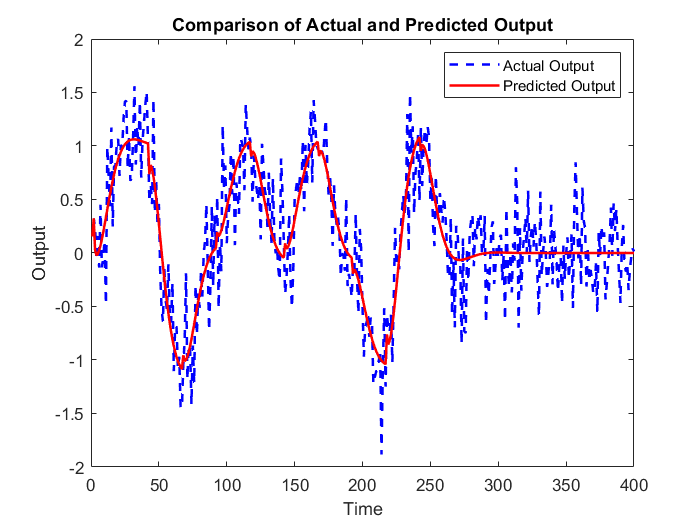

% Plot the actual output and predicted output
figure;
t = 1:length(output1);
plot(t, output1, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)    
  A(z) = 1 - 1.801 z^-1 + 0.8211 z^-2                        
                                                             
  B(z) = 0.1421 z^-1 - 0.3013 z^-2 + 0.216 z^-3 - 0.0365 z^-4
                                                             
  C(z) = 1 - 1.815 z^-1 + 0.8146 z^-2                        
                                                             
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=4   nc=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data.       
Fit to estimation data: 50.49% (prediction focus)
FPE: 0.09847, MSE: 0.09461                       


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.9400 + 0.4300i
   0.9400 - 0.4300i
   0.2404 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.9003 + 0.1024i
   0.9003 - 0.1024i



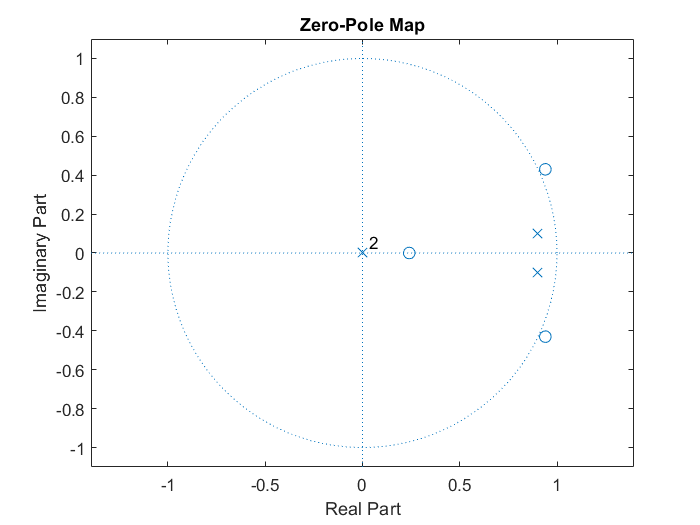


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6058



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3556



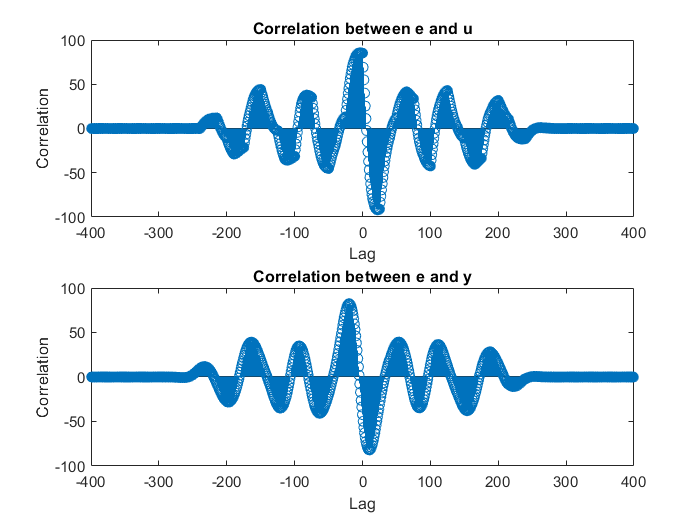


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
for na = na_values
    for nb = nb_values
        for nc = nc_values
            for nk = nk_values
                % ARMAX Model Identification
                sys = armax(iddata(output2, u.', 0.01), [na, nb, nc, nk]);
                sys.Ts = 0.01;  
                y_val_pred = compare(sys, iddata(output2, u.', 0.01)); 
                val_error = mean((y_val_pred.OutputData - output2).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nc = nc;
                    best_nk = nk;
                    best_model = sys;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;  
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 4


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 1


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0092807



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -0.0953 -1.2934 -0.3298 0.7874]
                 B: [0 0.0326 -0.0089 0.0314 0.0137]
                 C: [1 -0.0237 -1.2992 -0.4361 0.7590]
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0089
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



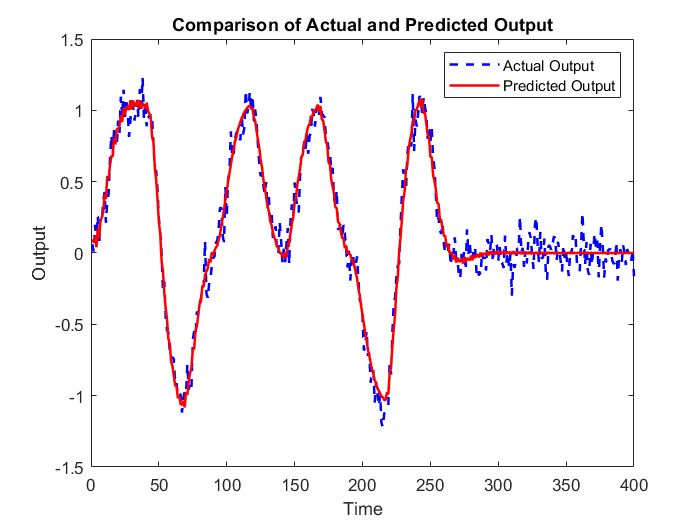

% Plot the actual output and predicted output
figure;
t = 1:length(output2);
plot(t, output2, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)         
  A(z) = 1 - 0.09527 z^-1 - 1.293 z^-2 - 0.3298 z^-3 + 0.7874 z^-4
                                                                  
  B(z) = 0.0326 z^-1 - 0.008868 z^-2 + 0.0314 z^-3 + 0.01371 z^-4 
                                                                  
  C(z) = 1 - 0.02373 z^-1 - 1.299 z^-2 - 0.4361 z^-3 + 0.759 z^-4 
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=4   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data.       
Fit to estimation data: 82.84% (prediction focus)
FPE: 0.009196, MSE: 0.008661                     


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   0.3133 + 1.0427i
   0.3133 - 1.0427i
  -0.3546 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

  -0.8531 + 0.4818i
  -0.8531 - 0.4818i
   0.9007 + 0.0946i
   0.9007 - 0.0946i



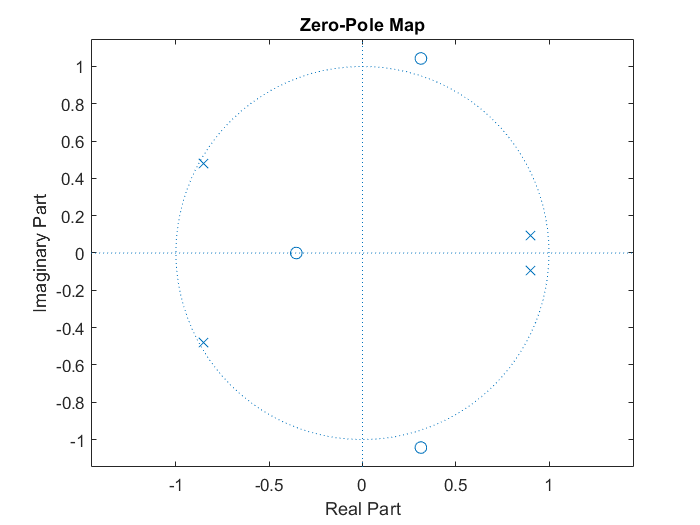


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6025



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3632



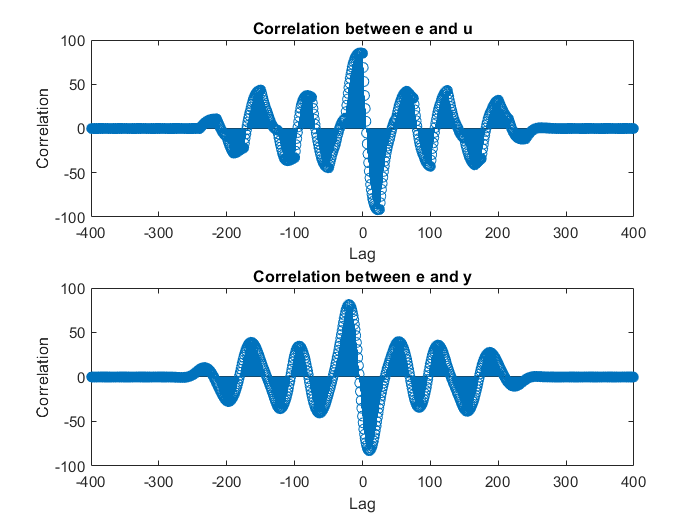


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_na = 0;            % Variable to store the best 'na' value
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
for na = na_values
    for nb = nb_values
        for nc = nc_values
            for nk = nk_values
                % ARMAX Model Identification
                sys = armax(iddata(output3, u.', 0.01), [na, nb, nc, nk]);
                sys.Ts = 0.01;  
                y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
                val_error = mean((y_val_pred.OutputData - output3).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_na = na;
                    best_nb = nb;
                    best_nc = nc;
                    best_nk = nk;
                    best_model = sys;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;  
                end
            end
        end
    end
end

% Display the best parameter values and validation error
disp(['Best na value: ', num2str(best_na)]);

Best na value: 4


disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 4


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 2


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0010903



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -1.1358 0.5913 -1.1999 0.7916]
                 B: [0 0 0.0417 0.0057 0.0111 -0.0113]
                 C: [1 -1.1667 0.6165 -1.2760 0.8358]
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0011
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



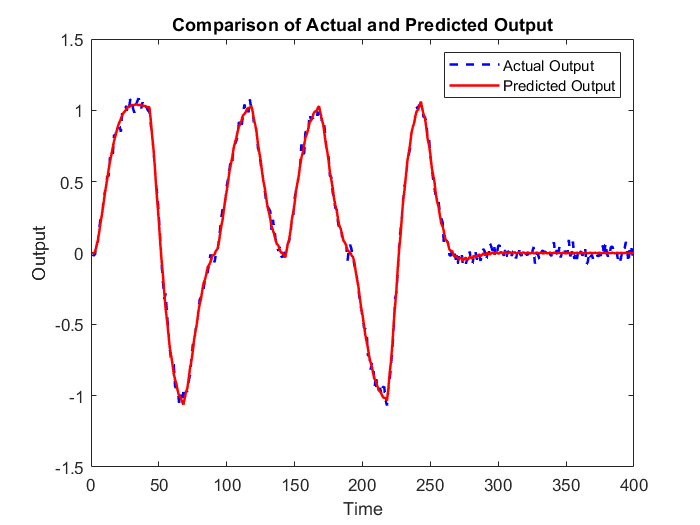

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)         
  A(z) = 1 - 1.136 z^-1 + 0.5913 z^-2 - 1.2 z^-3 + 0.7916 z^-4    
                                                                  
  B(z) = 0.0417 z^-2 + 0.005738 z^-3 + 0.01112 z^-4 - 0.01135 z^-5
                                                                  
  C(z) = 1 - 1.167 z^-1 + 0.6165 z^-2 - 1.276 z^-3 + 0.8358 z^-4  
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=4   nk=2
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data.       
Fit to estimation data: 93.83% (prediction focus)
FPE: 0.00112, MSE: 0.001055                      


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

  -0.3096 + 0.6849i
  -0.3096 - 0.6849i
   0.4816 + 0.0000i



disp('Poles:');

Poles:


disp(poles_est);

  -0.3319 + 0.9264i
  -0.3319 - 0.9264i
   0.8998 + 0.0889i
   0.8998 - 0.0889i



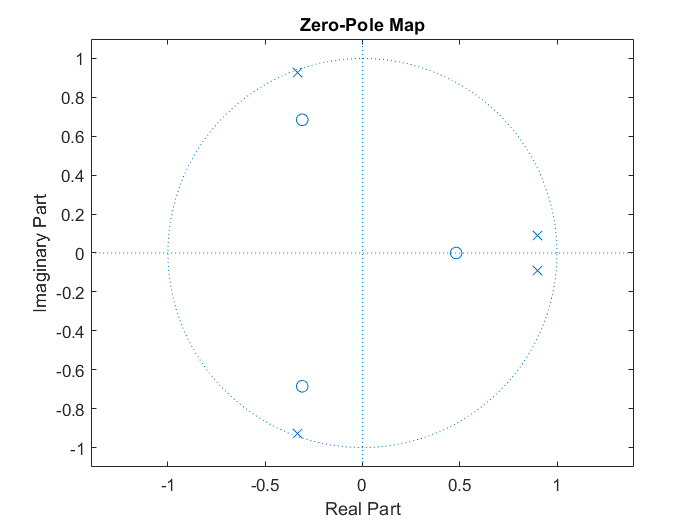


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');

e = u.' - best_y_pred;
corr_eu = corrcoef(e, u.');
corr_eu = corr_eu(1, 2); % Extract the correlation coefficient from the matrix

% Calculate the correlation between e and y
corr_ey = corrcoef(e, best_y_pred);
corr_ey = corr_ey(1, 2); % Extract the correlation coefficient from the matrix

% Display the correlation coefficients
disp('Correlation between e and u:');

Correlation between e and u:


disp(corr_eu);

    0.6092



disp('Correlation between e and y:');

Correlation between e and y:


disp(corr_ey);

   -0.3493



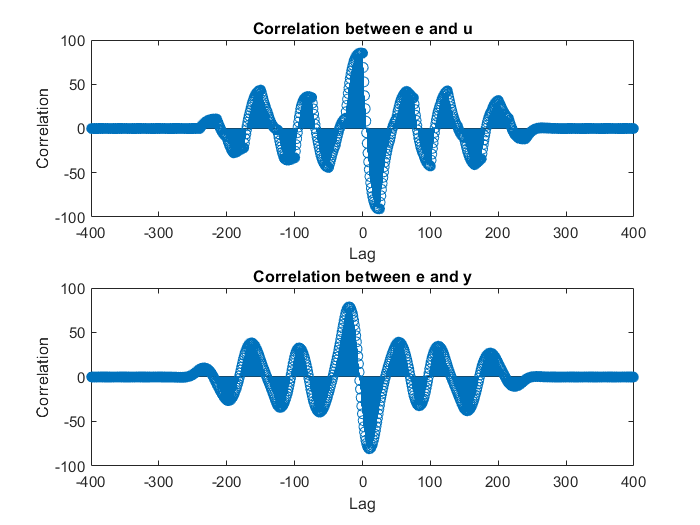


corr_eu = xcorr(e, u.');

% Calculate the correlation between e and y
corr_ey = xcorr(e, best_y_pred);

% Plot the correlation results
lags = -(length(e)-1):(length(e)-1);
figure;
subplot(2, 1, 1);
stem(lags, corr_eu);
title('Correlation between e and u');
xlabel('Lag');
ylabel('Correlation');
subplot(2, 1, 2);
stem(lags, corr_ey);
title('Correlation between e and y');
xlabel('Lag');
ylabel('Correlation');

% ARX with 0.01 noise
best_y_pred = [];  
best_nb = 0;            % Variable to store the best 'nb' value
best_nk = 0;            % Variable to store the best 'nk' value
best_nc = 0;            % Variable to store the best 'nk' value
best_nf = 0;            % Variable to store the best 'nk' value
best_nd = 0;            % Variable to store the best 'nk' value
best_val_error = Inf;   % Variable to store the best validation error
best_model = [];        % Variable to store the best model
% Loop over each combination of 'na', 'nb', 'nc', and 'nk' values
    for nb = nb_values
        for nc = nc_values
            for nk = nk_values
                % ARMAX Model Identification
                sys = armax(iddata(output3, u.', 0.01), [3, nb, nc, nk]);
                sys.Ts = 0.01;  
                y_val_pred = compare(sys, iddata(output3, u.', 0.01)); 
                val_error = mean((y_val_pred.OutputData - output3).^2);
                if val_error < best_val_error
                    best_val_error = val_error;
                    best_nb = nb;
                    best_nc = nc;
                    best_nk = nk;
                    best_model = sys;  % Store the best model
                    best_y_pred = y_val_pred.OutputData;  
                end
            end
        end
    end


% Display the best parameter values and validation error
disp(['Best nb value: ', num2str(best_nb)]);

Best nb value: 3


disp(['Best nc value: ', num2str(best_nc)]);

Best nc value: 4


disp(['Best nk value: ', num2str(best_nk)]);

Best nk value: 2


disp(['Best validation error (MSE): ', num2str(best_val_error)]);

Best validation error (MSE): 0.0011087



% Display the best model
disp('Best model:');

Best model:


disp(best_model);

  idpoly with properties:

                 A: [1 -0.8026 -0.9872 0.8246]
                 B: [0 0 0.0404 0.0140 -0.0198]
                 C: [1 -0.7803 -1.0428 0.7947 0.0571]
                 D: 1
                 F: 1
    IntegrateNoise: 0
          Variable: 'z^-1'
           IODelay: 0
         Structure: [1×1 pmodel.polynomial]
     NoiseVariance: 0.0011
            Report: [1×1 idresults.polyest]
        InputDelay: 0
       OutputDelay: 0
                Ts: 0.0100
          TimeUnit: 'seconds'
         InputName: {'u1'}
         InputUnit: {''}
        InputGroup: [1×1 struct]
        OutputName: {'y1'}
        OutputUnit: {''}
       OutputGroup: [1×1 struct]
             Notes: [0×1 string]
          UserData: []
              Name: ''
      SamplingGrid: [1×1 struct]



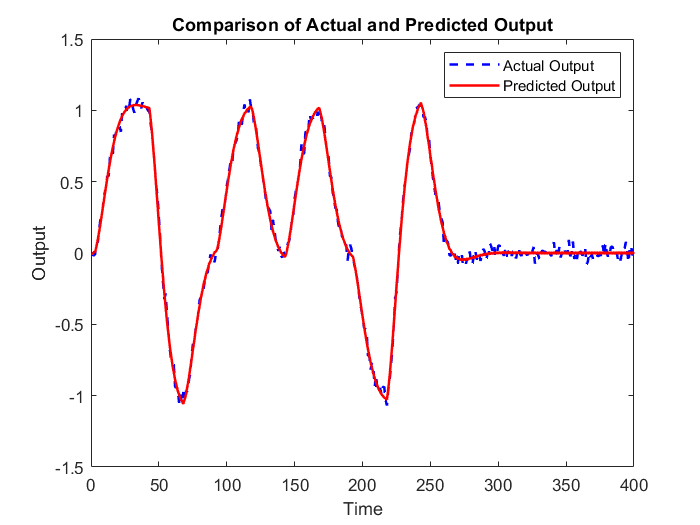

% Plot the actual output and predicted output
figure;
t = 1:length(output3);
plot(t, output3, 'b--', 'LineWidth', 1.5);
hold on;
plot(t, best_y_pred, 'r', 'LineWidth', 1.5);
hold off;
xlabel('Time');
ylabel('Output');
legend('Actual Output', 'Predicted Output');
title('Comparison of Actual and Predicted Output');

best_model

best_model =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)         
  A(z) = 1 - 0.8026 z^-1 - 0.9872 z^-2 + 0.8246 z^-3              
                                                                  
  B(z) = 0.0404 z^-2 + 0.01397 z^-3 - 0.01979 z^-4                
                                                                  
  C(z) = 1 - 0.7803 z^-1 - 1.043 z^-2 + 0.7947 z^-3 + 0.05713 z^-4
                                                                  
Sample time: 0.01 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=4   nk=2
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data.       
Fit to estimation data: 93.69% (prediction focus)
FPE: 0.001158, MSE: 0.001101                     


% Extract zeros and poles from the estimated ARX model
zeros_est = zero(best_model);
poles_est = pole(best_model);

% Display the zero locations and poles
disp('Estimated Model:');

Estimated Model:


disp('Zeros:');

Zeros:


disp(zeros_est);

   -0.8938
    0.5481



disp('Poles:');

Poles:


disp(poles_est);

  -1.0026 + 0.0000i
   0.9026 + 0.0889i
   0.9026 - 0.0889i



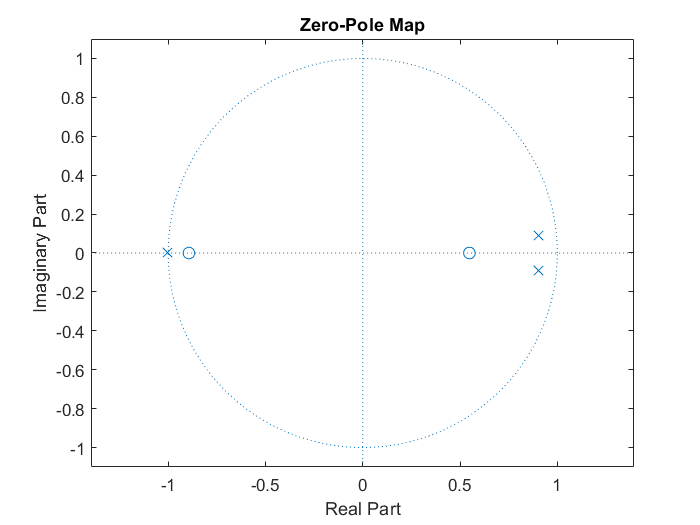


% Plot the zero-pole map
figure;
zplane(zeros_est, poles_est);
title('Zero-Pole Map');